*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* rock

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:10 |         2.69 |         2.95 |       7.2239 |       8.7177 |      1.0000e-04 |
|       5 |          30 |       00:15:59 |         1.76 |              |       3.0885 |              |      1.0000e-04 |
|       9 |          50 |       00:26:54 |         1.23 |         1.48 |       1.5085 |       2.19

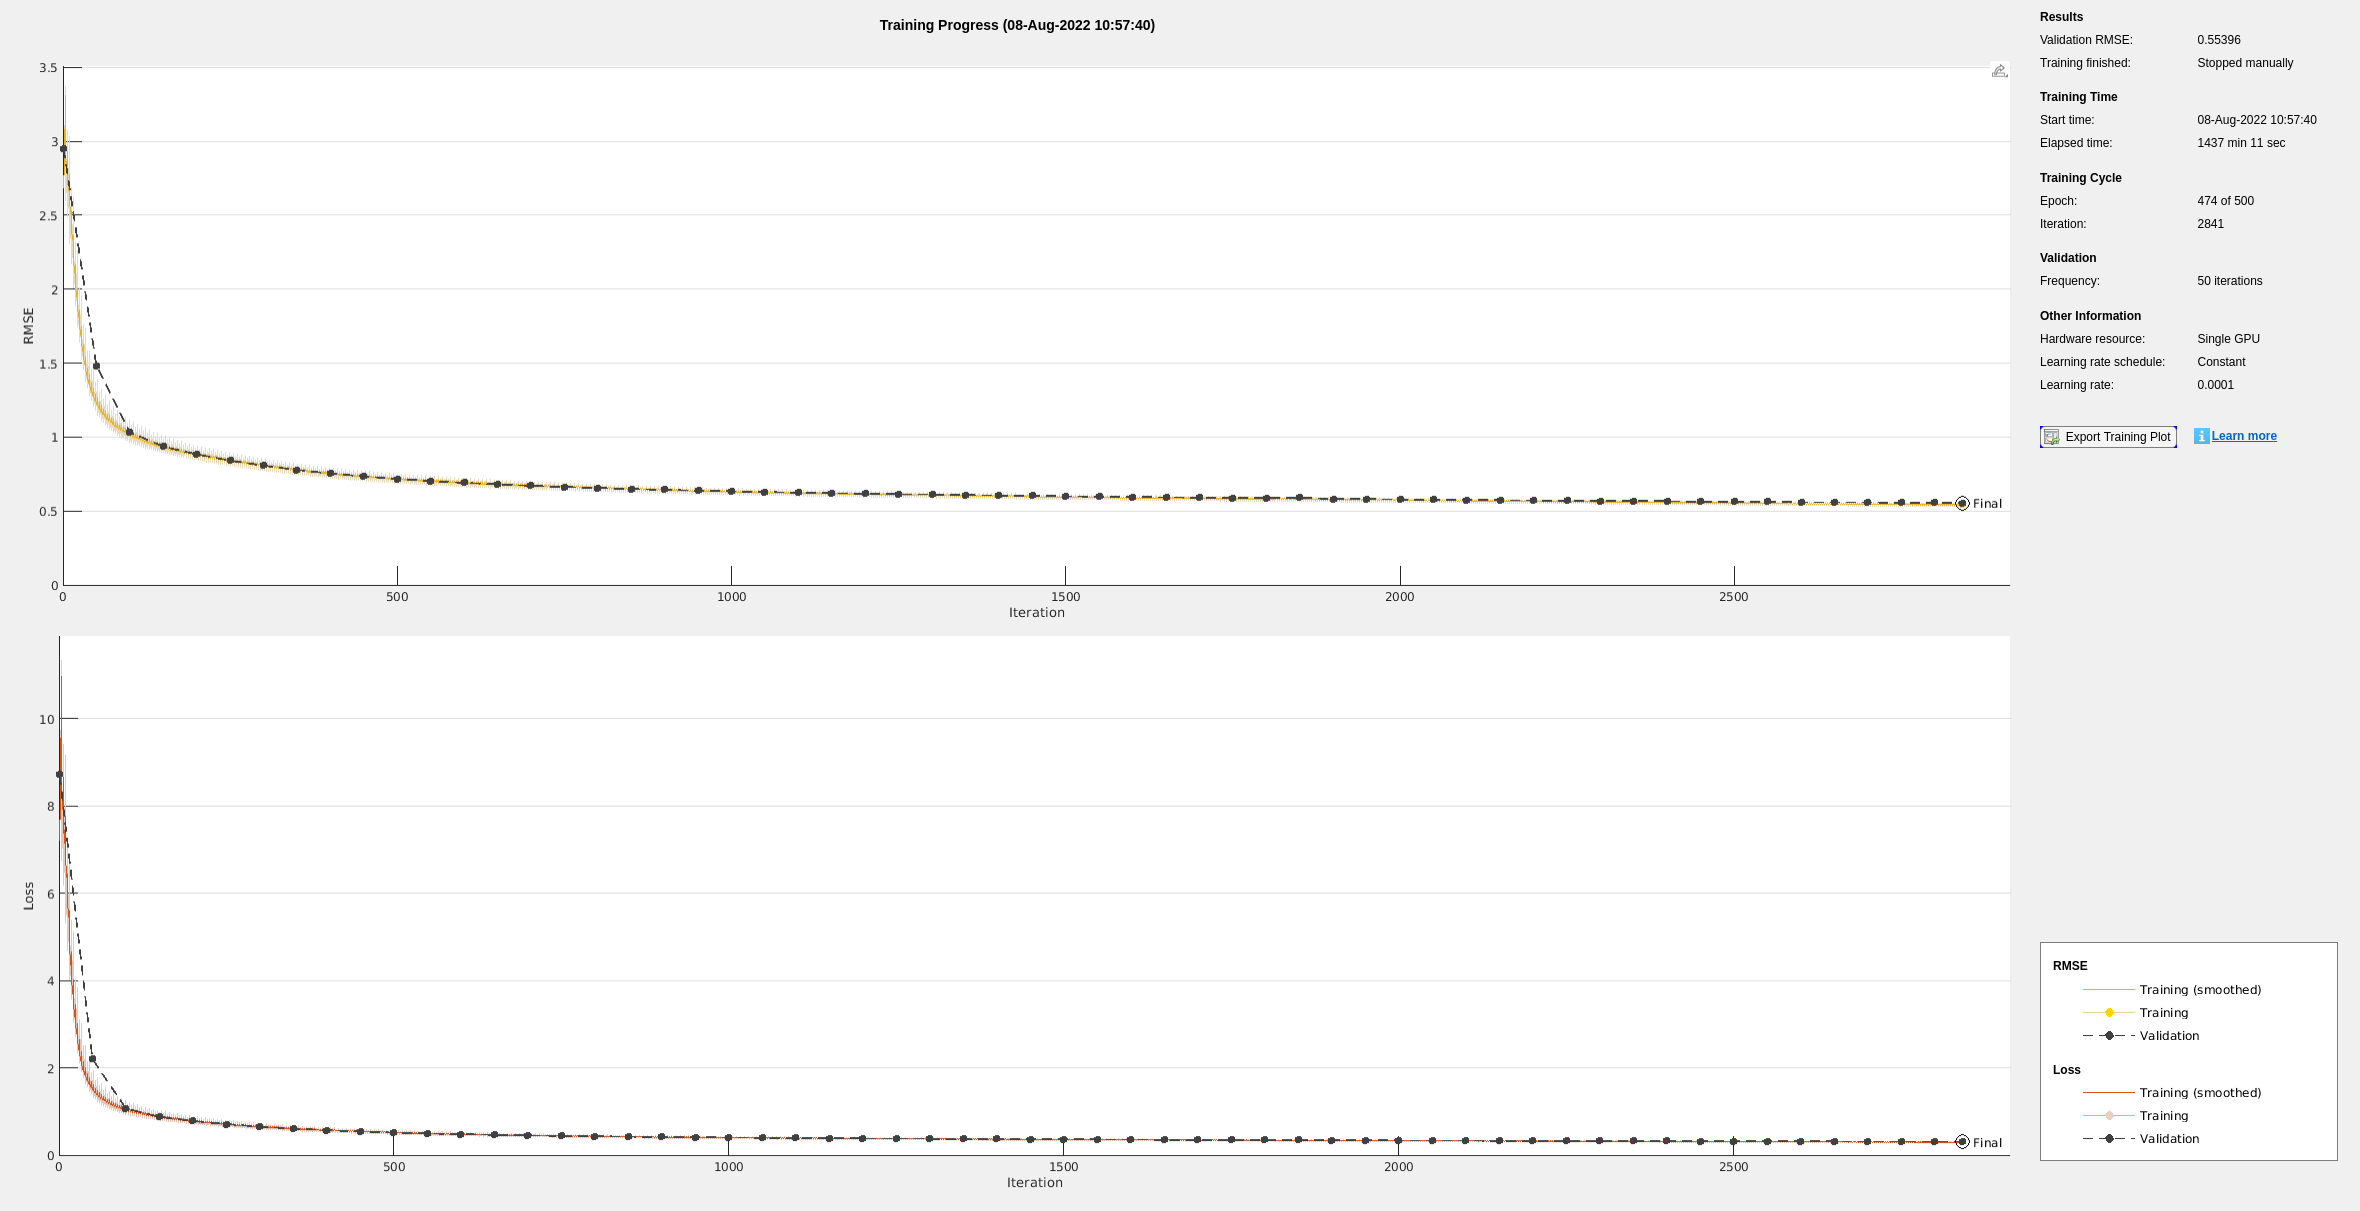

Detector training complete.
*************************************************************************



% This code trains a yolov2 detector that can be used to find rocks in our
% simulated dataset. We use the `default` model.

%   Copyright 2022 The MathWorks, Inc.

load data
rng(0, 'twister');
% Set validation partition to 2.5%. Keep in mind that we have stereo
% images, which means that we need to remove both Left and Right images for
% validation. This means that, in the end, we will have somewhere between
% 2.5 and 5% of validation data.
valThreshold = 0.025;
[trainIdx, valIdx] = validationSplit(data, valThreshold);

imdsTrain = imageDatastore(data.Filename(trainIdx));
bldsTrain = boxLabelDatastore(data(trainIdx, 2));
dsTrain = combine(imdsTrain, bldsTrain);

imdsVal = imageDatastore(data.Filename(valIdx));
bldsVal = boxLabelDatastore(data(valIdx, 2));
dsVal = combine(imdsVal, bldsVal);

selectedModel = 'default';

% We are not using validation data in our case, given that the variability
% of the obstacles (rocks) is small. E.g. they are quite similar to each
% other and with respect to the background. Overfitting here is not our
% biggest concern.
switch selectedModel
    case 'default'
        outputName = 'defaultDetector';        
        net = load('yolov2VehicleDetector.mat');
        lgraph = net.lgraph;
        lrate = 0.0001;
        optimizer = 'sgdm';
        batchSize = 3000; % 3000
    case 'resnet'
        outputNet = 'resnetDetector'        
        lrate = 0.00001;
        optimizer = 'sgdm';
        batchSize = 64;
        
        % From https://www.mathworks.com/help/vision/ref/yolov2layers.html
        network = resnet50();
        imageSize = [420, 560, 3];
        numClasses = 1;
        anchorBoxes = [1 1;4 6;5 3;9 6];
        featureLayer = 'activation_49_relu';
        lgraph = yolov2Layers(imageSize,numClasses,anchorBoxes,network,featureLayer);
end



chkpoints = 'logs';
options = trainingOptions(optimizer, ...
          'InitialLearnRate', lrate, ...
          'Verbose',true,...
          'MiniBatchSize',batchSize, ...
          'MaxEpochs',500,...
          'Shuffle','never',...
          'VerboseFrequency',30,...
          'CheckpointPath',chkpoints, ...
          'Plots', 'training-progress', ...
          'BatchNormalizationStatistics','moving', ...
          'ValidationData', dsVal);


[detector,info] = trainYOLOv2ObjectDetector(dsTrain,lgraph,options);

save(outputName, 'detector', 'info');